%%%%%%%%%%%%%%%%%%%%%%
%%%LK flag analysis
%%%created:10/24/22
%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/AQS %change to data folder

fn = "etoAQS NATTS.xlsx";

%SDK
Tatl = readtable(fn, "Sheet", "atlanta", "VariableNamingRule", "preserve"); 
%other NATTS 
Tother = readtable(fn, "Sheet", "not atlanta", "VariableNamingRule", "preserve");
sites = readtable("NATTS sites.xlsx", "sheet", "usedSites", "VariableNamingRule", "preserve");

Tall = [Tatl; Tother]; %append both together

cd ../..

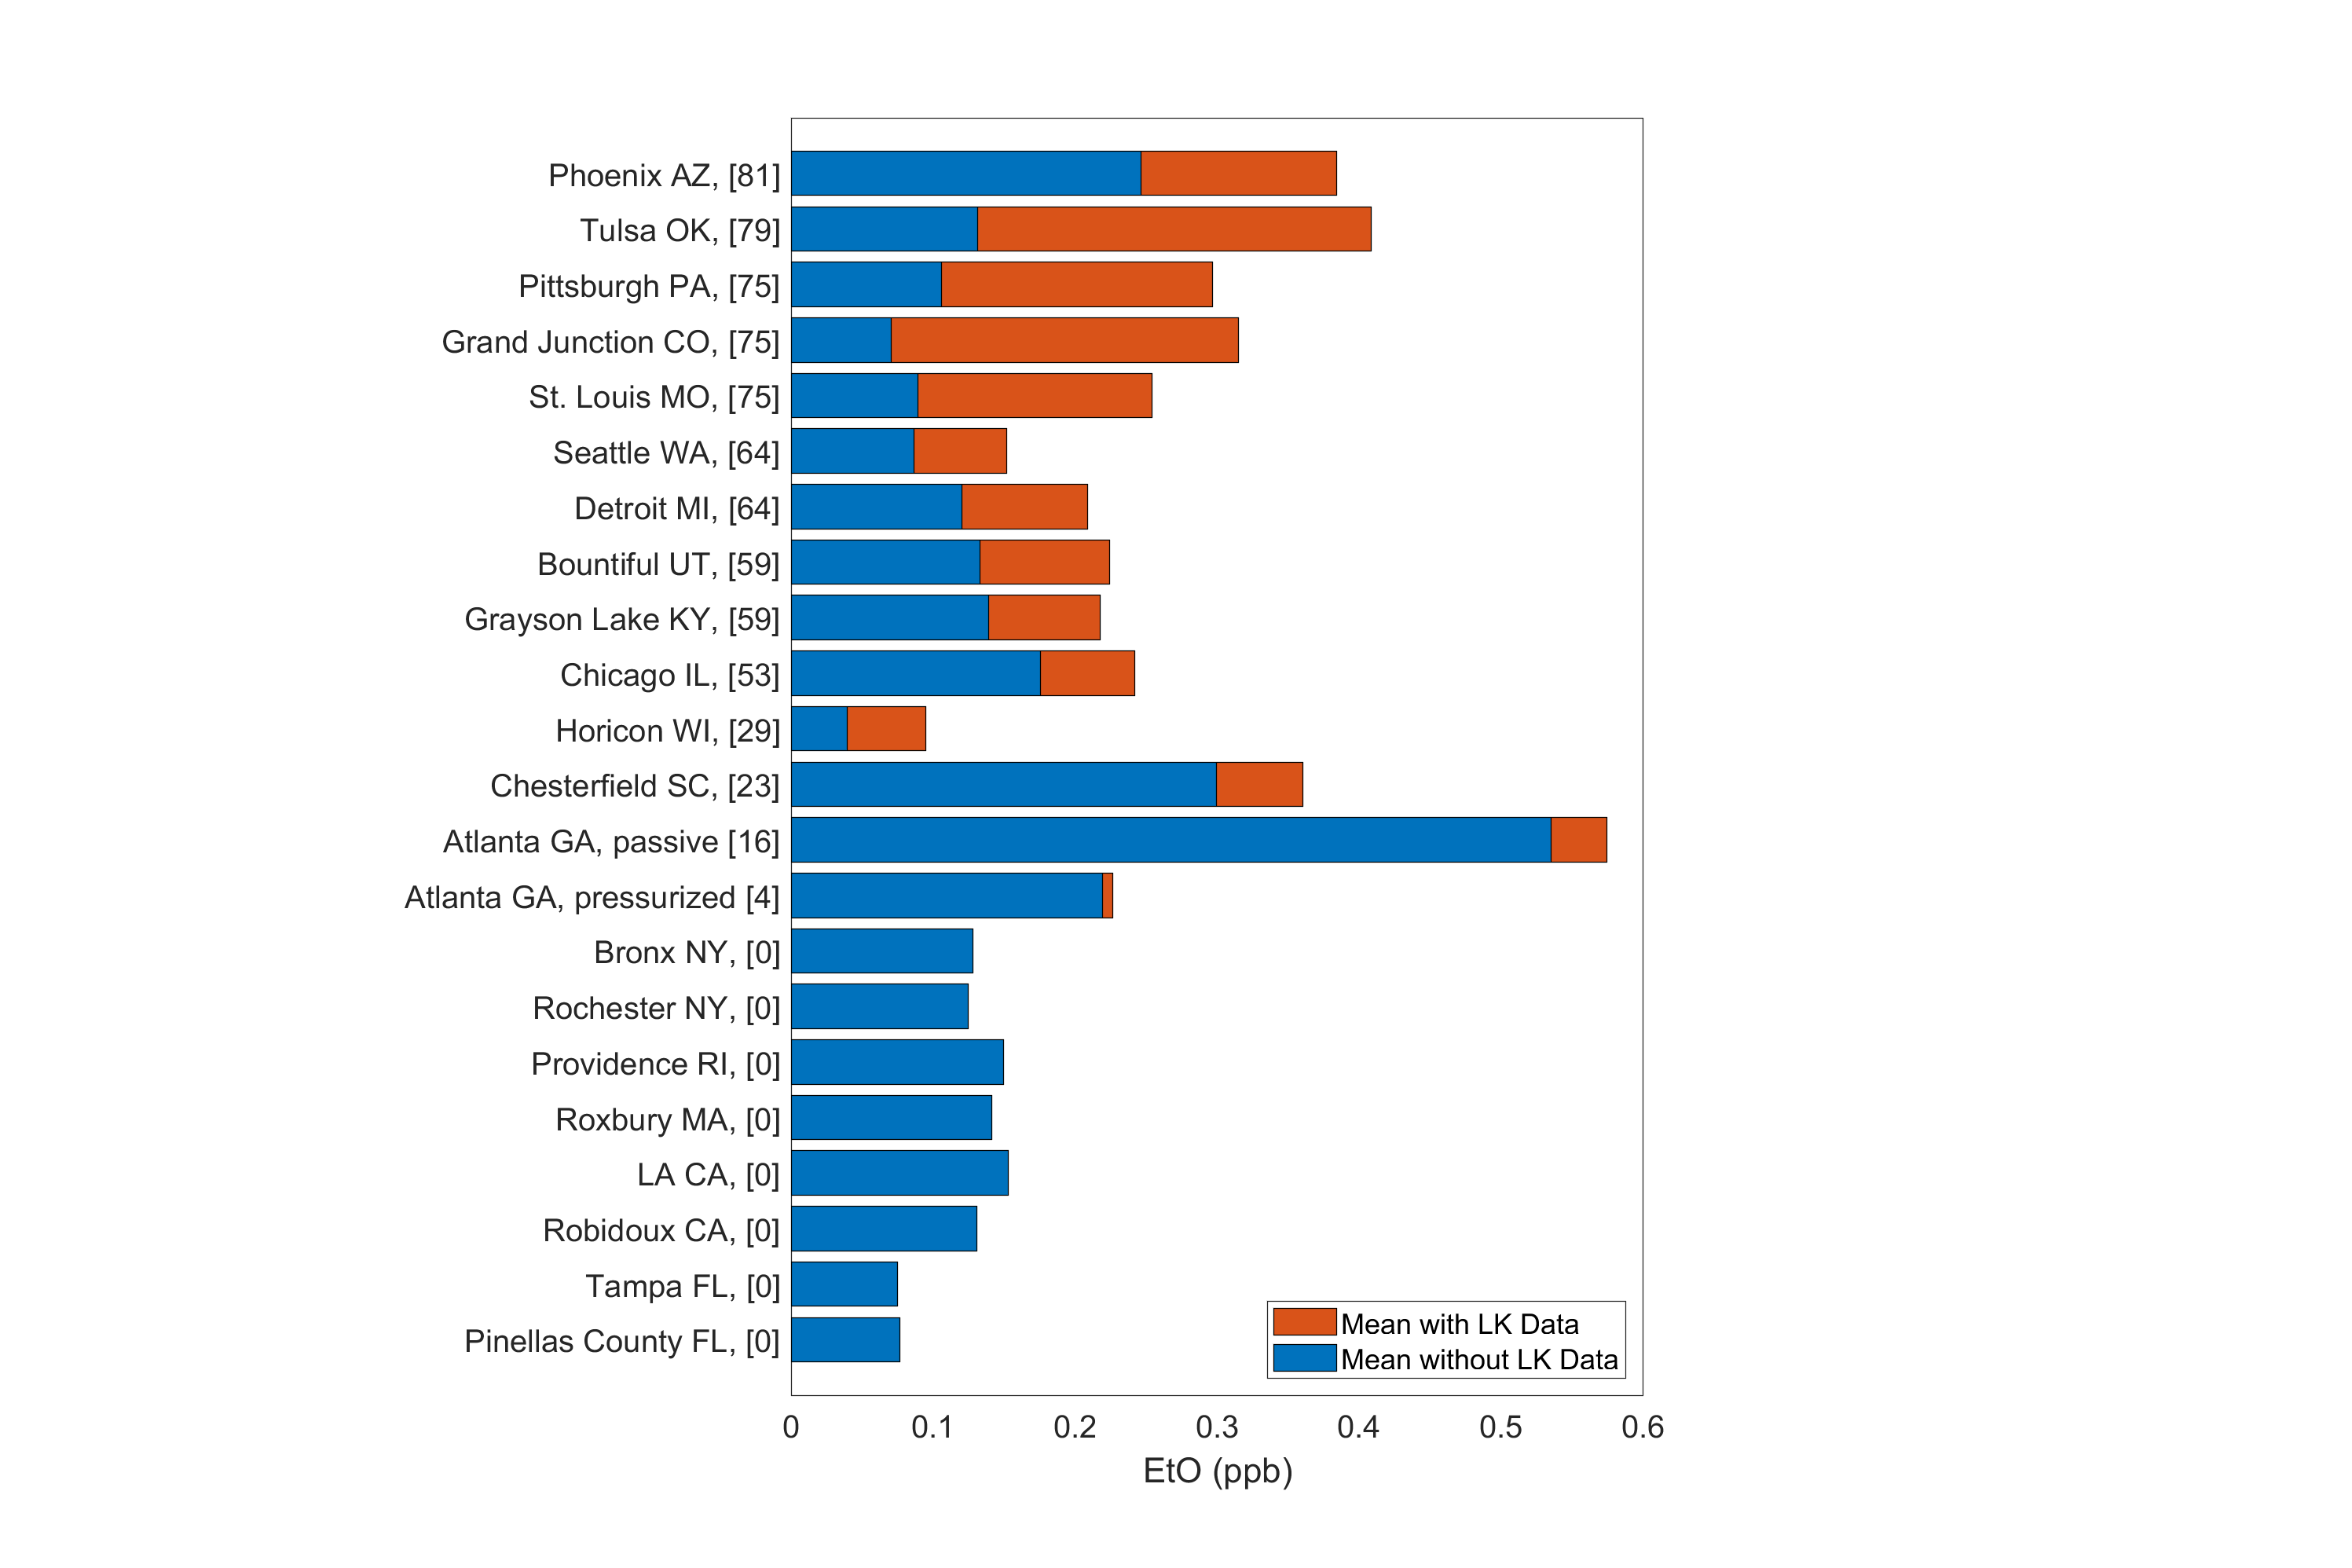

%%%grab all necessary data in table format
cities = unique(Tall.city);
TtoPlot = table();
TtoPlot.city = {cities{1}, cities{1}, cities{2:end}}'; %duplicate atlanta

for i = 1:length(TtoPlot.city)
    inds = ismember(Tall.city, TtoPlot.city(i)); %grab necessary city
    Tcurrent = Tall(inds, :);
    %%%special provision for Atl to get both methods(149, 150)
    if i == 1 %atlanta
        inds = ismember(Tcurrent.method_code, '149');
        Tcurrent = Tall(inds, :);
    elseif i == 2 %also atlanta
        inds = ismember(Tcurrent.method_code, '150');
        Tcurrent = Tall(inds, :);
    end
    
    %%populate table
    %grab state handle
    inds = ismember(sites.city, TtoPlot.city(i));
    TtoPlot.state(i) = sites.state(inds);
    TtoPlot.method(i) = Tcurrent.method_code(1); %method code
    TtoPlot.nTot(i) = size(Tcurrent, 1);
    %remove nans
    inds = isnan(Tcurrent.sample_measurement);
    TtoPlot.nNan(i) = sum(inds);
    Tcurrent(inds, :) = [];
    
    %calc initial stats
    TtoPlot.meanAll(i) = mean(Tcurrent.sample_measurement, "omitnan"); %mean
    TtoPlot.stdAll(i) = std(Tcurrent.sample_measurement, 0, "omitnan"); %std
    
    %do LK flag analysis
    inds = ismember(Tcurrent.qualifier, 'LK - Analyte Identified; Reported Value May Be Biased High.');
    TtoPlot.nLK(i) = sum(inds);
    Tcurrent(inds, :) = [];
    %calc LK stats
    TtoPlot.meanNoLK(i) = mean(Tcurrent.sample_measurement, "omitnan"); %mean
    TtoPlot.stdNoLK(i) = std(Tcurrent.sample_measurement, 0, "omitnan"); %std
    
    %calc % non-nan LK flagged
    TtoPlot.LKperc(i) = TtoPlot.nLK(i)/(TtoPlot.nTot(i)-TtoPlot.nNan(i))*100;
end

%%sort by descending LK % order
[~, inds] = sort(TtoPlot.LKperc);
TtoPlot = TtoPlot(flip(inds), :); %rearrange table

%re-sort 0s to align different methods
TtoPlot(15:end, :) = TtoPlot([22, 17, 19, 16, 21, 18, 15, 20], :);